clear;
im = imread("images_256\image_0001.jpg")

im = 256×256×3 uint8 array
im(:,:,1) =

   238   249   232   241   241   243   244   243   237   224   234   225   236   204   136   135   137   190   174   188   159   152   183   232   250   252   253   235   241   211   229   249   241   240   240   252   243   217   209   172   201   231   238   238   240   236   232   222   125   220   253   252   253   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   238   203   173   168   209   213   201   192   121    25    29    32    42    16    48    54    37    25     8    53    21    67    51    42    93    51    44    32    27    18    67    65    49    53    27    38    29    35    72    34    47    56    27    11    61    44    26    65    60    46    14    36    78    50    33    45    61    48    60    32    52    46    62    86    87    81    48    41

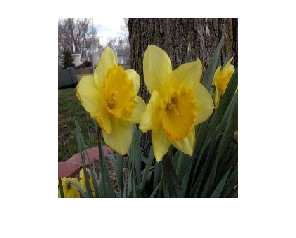

imshow(im)


imdir = "images_256"

imdir = "images_256"

labdir ="labels_256"

labdir = "labels_256"

outdir = "new_images_256"

outdir = "new_images_256"

mkdir(outdir)


if ~(isfolder(imdir) & isfolder(labdir))
    sprintf("error")
else
    imf = dir(fullfile(imdir, 'image_*.jpg'));
    laf = dir(fullfile(imdir, 'image_*.jpg'));

    for i = 1:numel(imf)
        imname = imf(i).name;
        label = [imname(1:end-4) '.png'];
        lpath = fullfile(labdir, label);
        if exist(lpath, 'file') == 2
            copyfile(fullfile(imdir, imname), fullfile(outdir, imname));
        end
    end
end